# Wideband Array Signal

This example shows how to simulate wideband signal received at the array.

## Define source signal

fs = 100e6;
t = (0:999).'/fs;
s = chirp(t,0,1e-4,fs);

## Define system information

fc = 300e6;                     % operating frequency
c = physconst("lightspeed");    % propagation speed

## Define spatial information

az_in = 30;                     % incoming direction

% you can try other directions, for example
% 
% az_in = 45;

## Define Array

antArray = phased.ULA("NumElements",5,"ElementSpacing",c/(2*fc));
sigCollector = phased.WidebandCollector(...
    "Sensor",antArray,"SampleRate",fs,...
    "CarrierFrequency",fc,"PropagationSpeed",c);

## Simulate signal

x = sigCollector(s,az_in);

## Add noise

rx = phased.Receiver("Gain",0,"NoiseMethod","Noise figure",...
    "NoiseFigure",125);
xn = rx(x);

## Plot

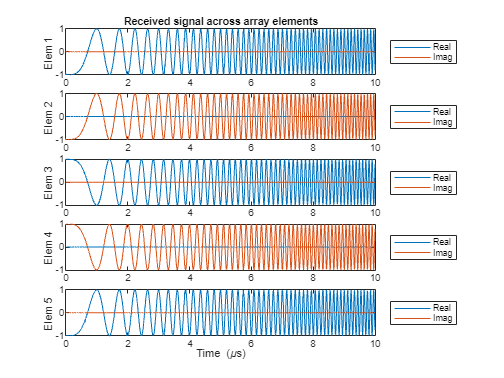

figure("Color","w");
x_plot = x;
% you can also plot the signal with noise
%
% x_plot = xn;

for m = 1:5
    subplot(5,1,m);
    plot(1e6*t,[real(x_plot(:,m)) imag(x_plot(:,m))]);
    ylim([-1 1]);
    ylabel(sprintf("Elem %d",m));
    legend("Real","Imag","Location","EastOutside")
end
subplot(5,1,5);
xlabel("Time (\mus)");
subplot(5,1,1);
title("Received signal across array elements");